# **3.1 Exercícios base**

#### **1. Considere a seguinte situação e responda às alíneas abaixo:**

#### Um aluno do primeiro ano de um curso de Engenharia tem todas as semanas 2 aulas Teórico-Práticas de uma Unidade Curricular X às 9:00, às quartas e sextas. Todos os dias que tem aulas desta UC, o aluno decide se vai à aula ou não da seguinte forma: Se tiver estado presente na aula anterior a probabilidade de ir à aula é 70%; se faltou à anterior, a probabilidade de ir é 80%.

(a) Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte? 

Sugestão: Comece por definir a matriz de transição de estados e o vetor estado correspondentes.

%% "Vai à aula" : 1
%% "Não vai à aula" : 0
T = [0.70 0.80 ;
    0.30 0.20]

T =     0.7000    0.8000
    0.3000    0.2000


v = [1  
    0];

%% Função que verifica se a matriz é estocástica ou não.
StocaticChecker(T);

A matriz em questão é estocástica



probs = T * T * v;
probIr = probs(1);
fprintf("A probabiliade do aluno ir à aula de quarta, sabendo que foi na quarta passada é: %.2f", probIr);

A probabiliade do aluno ir à aula de quarta, sabendo que foi na quarta passada é: 0.73

(b) Se não estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

v = [0
    1];
probs = T * T * v;
probNaoIr = probs(2);
fprintf("A probabiliade do aluno ir à aula de quarta, sabendo que não foi na quarta passada é: %.2f", probNaoIr);

A probabiliade do aluno ir à aula de quarta, sabendo que não foi na quarta passada é: 0.28

(c) Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na última aula, assumindo que o semestre tem exactamente 15 semanas de aulas e não existem feriados?

nAulas = 2*15;

T = T^(nAulas-1);
probs = T * v;
probIr = probs(1);
fprintf("A probabiliade do aluno ir à última, sabendo que foi à primeira é: %.12f", probIr);

A probabiliade do aluno ir à última, sabendo que foi à primeira é: 0.727272727273

(d) Represente num gráfico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula é de 85%.

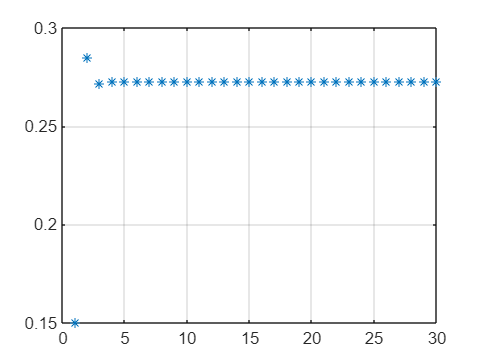

p1 = 1 - 0.85;
probArray = zeros(1,30);
probArray(1) = p1;
T = [0.70 0.80
    0.30 0.20];
v = [0.85 ; 0.15];
for i = 2:30
    probs = T^(i-1) * v;
    probArray(i) = probs(2); 
end

plot(probArray, "*");
grid on;

**2. Considere a seguinte “dança” de grupos: Divide-se uma turma em 3 grupos (A, B e C) no início do semestre e no final de cada aula efectuam-se os seguintes movimentos:**

• 1/3 do grupo A vai para o grupo B e outro 1/3 do grupo A vai para o grupo C;

• 1/4 do grupo B vai para A e 1/5 de B vai para C

• Metade do grupo C vai para o grupo B; a outra mantém-se no grupo C.

(a) Crie em Matlab a matriz de transição de estados que representa as trocas entre grupos. Confirme que se trata de uma matriz estocástica.

T = [1/3 1/4 0
    1/3 11/20 1/2 
    1/3 1/5 1/2]

T =     0.3333    0.2500         0
    0.3333    0.5500    0.5000
    0.3333    0.2000    0.5000



StocaticChecker(T);

A matriz em questão é estocástica


(b) Crie o vector relativo ao estado inicial considerando que no total temos 90 alunos, o grupo A tem o dobro da soma dos outros dois e os grupos B e C têm o mesmo número de alunos.

nTotal = 90;
nA = 60;
nB = 15;
nC = nB;
x0 = ([nA nB nC])';

c) Quantos elementos integrarão cada grupo no fim da aula 30 considerando como estado inicial o definido na alínea anterior?

probs = T^(30-1) * x0;
nA = probs(1);
nB = probs(2);
nC = probs(3);
fprintf("A: %d\nB: %d\nC: %d",nA,nB,nC);

A: 1.666667e+01
B: 4.444444e+01
C: 2.888889e+01

(d) Quantos elementos integrarão cada grupo no fim da aula 30 considerando que inicialmente se distribuiram os 90 alunos equitativamente pelos 3 grupos?

x0 = [30 30 30]';
probs = T^(30-1) * x0;
fprintf("A: %d\nB: %d\nC: %d",probs(1),probs(2),probs(3));

A: 1.666667e+01
B: 4.444444e+01
C: 2.888889e+01

function [] = StocaticChecker (matriz)
    n = sum(matriz);
    if (length(n) == sum(n))
        fprintf("A matriz em questão é estocástica\n");
    else
        fprintf("A matriz em questão não é estocástica\n");
    end
end